clc
clear
n = 385;
N = n^2;
A = gallery('poisson', n);
fprintf(['\nDimensione matrice dei coefficienti A: '...
         '%u x %u \n\n'],N,N);


Dimensione matrice dei coefficienti A: 148225 x 148225 



disp(full(A(1:5, 1:5)));

     4    -1     0     0     0
    -1     4    -1     0     0
     0    -1     4    -1     0
     0     0    -1     4    -1
     0     0     0    -1     4



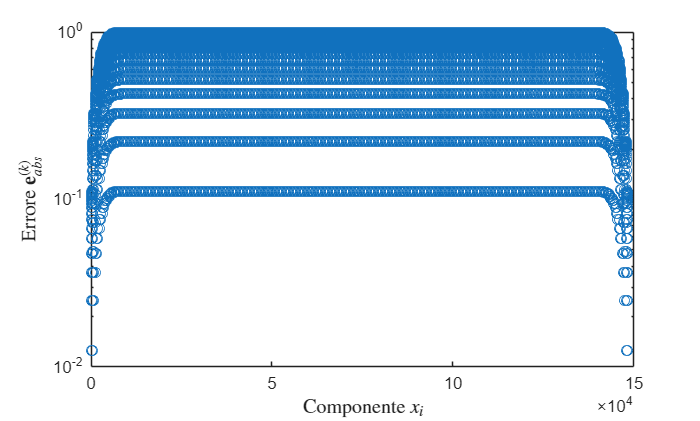

b = sum(A,2);
x = ones(N,1);

[xJM1,flagJM1,relresJM1,iterJM1,resvecJM1] = jacobi(A,b);
% Calcolo dell'errore assoluto
errJM1 = abs(x - xJM1);
% Rappresentazione grafica errore assoluto
figure(1)
semilogy(errJM1, 'o');
ylabel('$\|\mathbf{e}^{(k)}\|$', 'Interpreter','latex','FontSize',16);
xlabel('$x_{i}$', 'Interpreter','latex','FontSize',16);

if flagJM1 == 1
fprintf("jacobi si è fermato all'iterazione numero %u senza " + ...
        "raggiungere la tolleranza desiderata %0.2g\n" + ...
        "poiché il numero massimo di iterazioni %u " + ...
        "è stato raggiunto.\nL'ultima iterazione presenta residuo relativo pari a %0.2g.\n", ...
        iterJM1, 1e-6, 100, relresJM1);
end

jacobi si è fermato all'iterazione numero 100 senza raggiungere la tolleranza desiderata 1e-06
poiché il numero massimo di iterazioni 100 è stato raggiunto.
L'ultima iterazione presenta residuo relativo pari a 0.028.


maxit = 3e5;

tJM2 = tic;
[xJM2,flagJM2,relresJM2,iterJM2,resvecJM2] = jacobi(A,b,[],maxit);
tJM2 = toc(tJM2);

if flagJM2 == 0
     fprintf("jacobi ha raggiunto la convergenza all'iterazione %u, calcolando " + ...
             "una soluzione approssimata avente residuo relativo\npari a %0.2g.\n",iterJM2,relresJM2);
    xJM2par = xJM2(1:10)
     fprintf("Tempo di esecuzione per il metodo di Jacobi: %f sec.", tJM2);
end

jacobi ha raggiunto la convergenza all'iterazione 210137, calcolando una soluzione approssimata avente residuo relativo
pari a 1e-06.


xJM2par =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


Tempo di esecuzione per il metodo di Jacobi: 437.693564 sec.

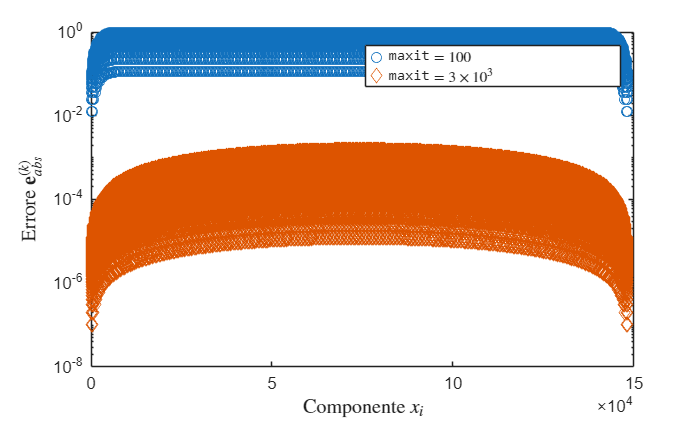

errJM2 = abs(x - xJM2);

figure(2)
semilogy(errJM1,'o');
hold on
semilogy(errJM2,'diamond');
ylabel('$\|\mathbf{e}^{(k)}\|$', 'Interpreter','latex','FontSize',12);
xlabel('$x_{i}$', 'Interpreter','latex','FontSize',12);
legend('I tentativo','II tentativo');
hold off

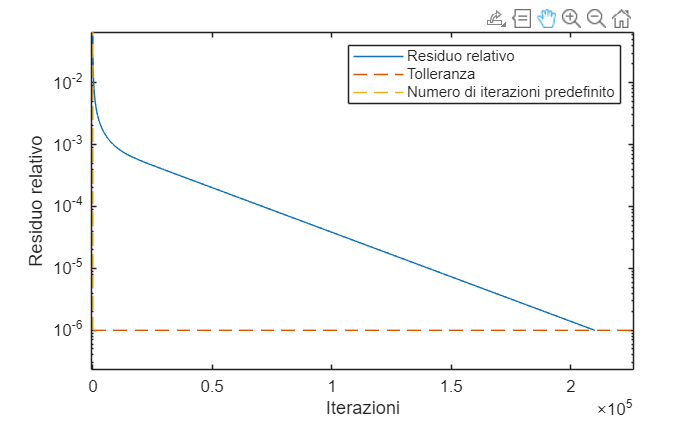

relresvecJM = resvecJM2./resvecJM2(1);
tol = 1e-6;
idx1 = find(relresvecJM > tol, 1, 'last');

if isempty(idx1) || idx1 == length(relresvecJM)
    disp('Intersezione non trovata o avviene all''ultimo punto. Impossibile interpolare.');
    return;
end

% Indice del punto successivo
idx2 = idx1 + 1;

% Coordinate dei  punti che definiscono il segmento
p1 = [idx1, relresvecJM(idx1)];
p2 = [idx2, relresvecJM(idx2)]; 

% Calcolo dell'intersezione tramite interpolazione lineare .
px = p1(1) + (tol - p1(2)) * (p2(1) - p1(1)) / (p2(2) - p1(2));
py = tol; 

figure(3)
f=semilogy(relresvecJM);
hold on
semilogy(f.Parent.XLim,[tol, tol],'--')
p = plot(px, py, 'p');

% 2. Crea un datatip e ATTACCALO all'handle del punto appena creato.
dt = datatip(p);
dt.Visible = 'on';

ylabel('Residuo relativo');
xlabel("Iterazioni");
legend('Residuo relativo','Tolleranza')
hold off

xlim([-7.2357e+02, 2.2655e+05])
ylim([2.2975e-07, 6.5433e-02])
zlim([-1.0000e+00, 1.0000e+00])

% % Generazione array distribuiti
% n = 10;
% A = distributed((gallery('poisson', n)));
% b = sum(A,2);
% 
% % III tentativo - Metodo di jacobi con supporto agli array distribuiti
% tJM3 = tic;
% [xJM3,flagJM3,relresJM3,iterJM3,resvecJM3] = jacobi(A,b,[],maxit);
% tJM3 = toc(tJM3);
% if flagJM3 == 0
%      fprintf("jacobi ha raggiunto la convergenza all'iterazione %u, calcolando " + ...
%              "una soluzione approssimata con residuo relativo pari a %0.2g.\n",iterJM3,relresJM3);
% end
% % speedup = tJM2/tJM3
% % fprintf("Tempo di esecuzione per il metodo di jacobi con array distribuiti: %f sec.", tJM3);
% % fprintf("Speedup attribuibile alla parallelizzazione: %f", speedup);